Plot the Results from an Ariane Run

1) Bathymetry has been downloaded from erddap as a netcdf file and renamed as bathymetry.nc

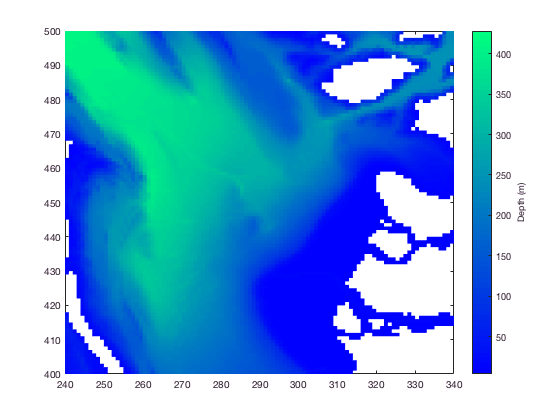

bathy = ncread('bathymetry.nc', 'bathymetry');
model_lats = ncread('bathymetry.nc', 'latitude');
model_lons = ncread('bathymetry.nc', 'longitude');
h = pcolor(bathy');
set(h, 'EdgeColor', 'none');
ax1=gca;
colormap(flipud('winter'));
cb = colorbar;
cb.Label.String = 'Depth (m)';
axis([240 340 400 500]);
hold on;

2) plot the trajectories

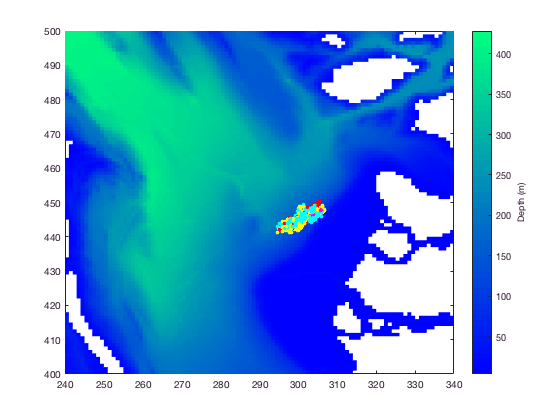

hold on;
colour = ['r', 'y', 'c', 'm'];
load('mytrajectories.mat')
traj = reshape(ally, length(allt), 27, 3);
for i=1:50:length(allt)
    for j=1:27
        c = ceil((traj(i, j, 1) - 25)) + 1;
        c = max([1 min([c 4])]);
        plot(traj(i, j, 3), traj(i, j, 2), ...
            'o', 'MarkerFaceColor', colour(c), 'MarkerEdgeColor', colour(c),...
        'MarkerSize', 3)
    end
end

3) add the outfall location

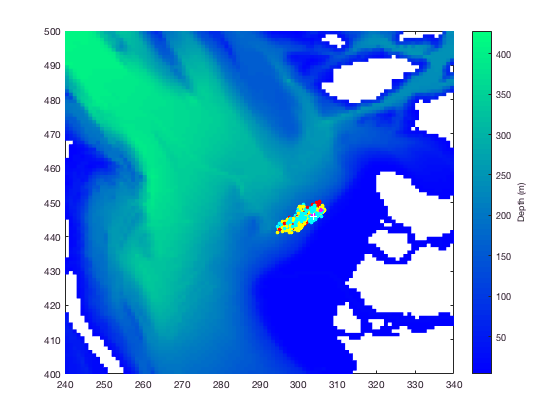

plot(304, 446, '+k');
hold off;

4) And now how to plot the velocity field.  We are on a staggered grid with the u-velocity 1/2 grid point in x and -1/2 grid point in y away from the v-velocity.  The files are huge, so we select what we want (choosing first hour and 27 grid point down) and then clear the big array

uvel_all = ncread('uVelocity_2016apr09_01.nc', 'uVelocity');
uvel = squeeze(uvel_all(:, :, 27, 1));
clear('uvel_all');
vvel_all = ncread('vVelocity_2016apr09_01.nc', 'vVelocity');
vvel = squeeze(vvel_all(:, :, 27, 1));
clear('vvel_all');
depths = ncread('uVelocity_2016apr09_01.nc', 'depth');
depths(27)

Unstagger

[u1, v1] = unstagger(uvel, vvel);

Rotate from grid coordindates to real north/east

[ueast, vnorth] = rotate_vel(u1, v1);

Plot

h = pcolor(model_lons, model_lats, bathy);
set(h, 'EdgeColor', 'none');
ax1=gca;
colormap(flipud('winter'));
cb = colorbar;
cb.Label.String = 'Depth (m)';
axis([-123.5 -123.1 49.05 49.35]);
xlabel('longitude');
ylabel('latitude');
hold on;
lowx = 250; higx=350; lowy=400; higy=500;
quiver(model_lons(lowx:3:higx, lowy:3:higy), model_lats(lowx:3:higx, lowy:3:higy),...
    ueast(lowx-1:3:higx-1, lowy-1:3:higy-1), vnorth(lowx-1:3:higx-1, lowy-1:3:higy-1), 'w')
hold off;